# Diferenciación Numérica

[repositorio de github](https://github.com/rorode8/NumericalDifferentiation-matlab)

La diferenciación númerica aproxima el valor de una de la derivada de una función utilizando una serie de puntos, la cual puede ser dada o se pueden obtener de la misma función pasada como parámetro.

## Introducción

La diferenciación numérica no es un proceso particularmente preciso. Sufre de un conflicto entre errores de redondeo (debido a la precisión limitada de la máquina) y errores de truncamiento. Por esta razón, el valor de la derivada calculada mediante diferenciacion numerica nunca tendrá la misma precisión que la derivada de la función evaluada en cierto punto *x.*

syms f(x);

El método utilizado para aproximar será la *aproximacion diferencial finita (Finite Difference Approximation)* El cual se apoya en las Series de Taylor alrededor de *x. *En especifico tratamos de aproximar los valores de $f(x+(n)h) \quad \textrm{y} \quad f(x-(n)h) $ para alguna n mayor a 0. Resolver sistemas de ecuaciones de estas series resulta en una aproximación de las derivadas de $f\left(x\right)$[1]. Esto tiene como consecuencia que existan dos fuentes de error inevitables antes mencionadas[2]:

- redondeo de la maquina (debido a la precisión limitada)

- error de truncamiento de las series de taylor (no planeamos resolverlas hasta converger, sino truncarlas en cierto punto)

## Series de Taylor

Por definición, la aproximación con una serie de taylor par auna función $$f(x)$$ alderedor del punto $$a$$ es:


$$f\left(x\right)\;\approx f\left(a\right)+\frac{f^{\prime } \left(a\right)}{1!}\left(x-a\right)+\frac{f^{\prime \prime } \left(a\right)}{2!}{\left(x-a\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(a\right)}{n!}{\left(x-a\right)}^n$$


Ahora, si aproximamos en funcion de $x+h$ alrededor de un punto $x$


$$f\left(x+h\right)\approx f\left(x\right)+\frac{f^{\prime } \left(x\right)}{1!}\left(h\right)+\frac{f^{\prime \prime } \left(x\right)}{2!}{\left(h\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(x\right)}{n!}{\left(h\right)}^n$$


## Primera derivada

Resolviendo varias funciones de taylor, podemos despejar la primera derivada de x de la ecuacion resultante al substraer de la serie de f(x+h) alrededor de x de la serie de f(x-h) alrededor de x.[1]


$$f\left(x+h\right)-f\left(x-h\right)\approx 2\left\lbrack {\textrm{hf}}^{\prime } \left(x\right)+\frac{h^3 }{3!}f^{\prime \prime \prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right\rbrack$$


despejando para ${f}'(x)$


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{1}{h}\left(\frac{h^3 }{3!}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{h^2 }{6}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)-\ldotp \ldotp \ldotp$$


por lo que si fijamos x y variamos h para identificar la precisión de la aproximación, podemos asumir que el error de truncamiento se comporta como $h^2$. Es decir,

$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$$+ \mathcal{O}(h^2)$$,

ya que *h *es la mayoria de las veces menor a 1 y, a mayor grado de exponente en *h*, mejor es la aproximación.

En el caso de querer mejorar la precisión, deberiamos calcular más series de Taylor como funciones de $x\pm (n)h$ y cancelaras entre sí.

## Generalización

Usando el método anteriormente descrito, llegamos a tres formas distintas, las aproximaciones centradas, hacia adelante y hacia atrás. Analizaremos la primera y la segunda derivada de las función:

f(x)=tanh(2*x)

$$f(x) = \tanh\left(2\,x\right)$$

format long
func1 = matlabFunction(f(x));
pow=0.6;                              % h expansion factor
lim = 50;                             % h highest exponent
i = 1:lim;                              
arr = @(x) double(power(pow,x));
hs = arr(i);                          % number of h -> hs = [h^1,..,h^i,...h^lim] where h<1

En particular calcularemos la derivada cuando:

x=2                                 % x to calculate the derivative at

x =      2


## Diferencia Central Finita

Las aproximaciones pueden realizarse de forma "centralizada", este nombre proviene de la necesidad de calcular los puntos $f\left(x+h\right)$ y $f\left(x-h\right)$ para una x que se encuentra en el centro de estos dos. 

    Usaremos las dos siguientes formulas para aproximar la primera y segunda derivada de las funciones.


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$

$$$+ \mathcal{O}(h^2)$$$



$$f^{\prime \prime } \left(x\right)\approx \frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$$

$$$+ \mathcal{O}(h^2)$$$


%calcular valor real
df      = diff(f)              %Primer derivada 

$$df(x) = 2-2\,{\tanh\left(2\,x\right)}^{2}$$

df_x    = double(df(x))        % real value of df/dx (x)

df_x =    0.002681901366052


d2f     = diff(f,2)            %Segunda derivada

$$d2f(x) = 4\,\tanh\left(2\,x\right)\,\left(2\,{\tanh\left(2\,x\right)}^{2}-2\right)$$

df2_x   = double(d2f(x))       % real value of d^2f/dx^2 (x)

df2_x =   -0.010720410456423



error           = zeros([10,length(hs)]);
approximations  = zeros([1,10]);

tabErrors= zeros(10,2);

Calculamos al principio y una sola vez las derivadas y los errores centrales, hacia adelante y hacia atrás. 

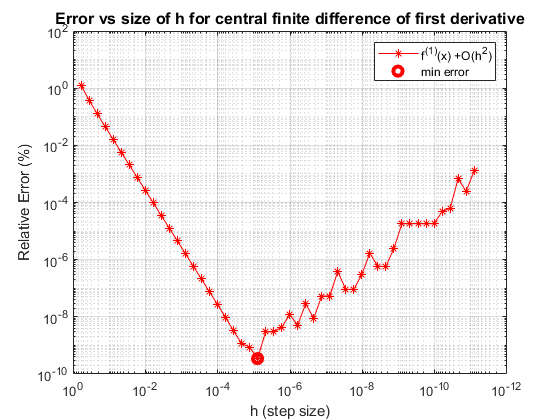

j=1;
for h = hs  
    % para cada valor de h calculamos la aproximación para cada una de las
    % funciones, en total tenemos 10. 2 centradas, 4 hacia adelante y 4
    % hacia atrás
    approximations(1) = firstCenteredDerivative(func1,x,h);     %centered first derivative - h^2
    approximations(2) = secondCenteredDerivative(func1,x,h);    %centered second derivative - h^2
    approximations(3) = forwardFiniteDifference(func1,x,h,1,1); %forward Finite first derivative -h
    approximations(4) = forwardFiniteDifference(func1,x,h,1,2); %forward Finite first derivative -h^2
    approximations(5) = forwardFiniteDifference(func1,x,h,2,1); %forward Finite second derivative -h
    approximations(6) = forwardFiniteDifference(func1,x,h,2,2); %forward Finite second derivative -h^2
    approximations(7) = backwardFiniteDifference(func1,x,h,1,1);%backward Finite first derivative -h
    approximations(8) = backwardFiniteDifference(func1,x,h,1,2);%backward Finite first derivative -h^2
    approximations(9) = backwardFiniteDifference(func1,x,h,2,1);%backward Finite second derivative -h
    approximations(10)= backwardFiniteDifference(func1,x,h,2,2);%backward Finite second derivative -h^2
    
    % calculamos el error relativo para cada aproximación.
    % nota que se usan diferentes valores para las primeras derivadas y las
    % segundas derivadas
    error(1,j)=abs(approximations(1)/df_x -1);
    error(2,j)=abs(approximations(2)/df2_x -1);
    error(3,j)=abs(approximations(3)/df_x -1);
    error(4,j)=abs(approximations(4)/df_x -1);
    error(5,j)=abs(approximations(5)/df2_x -1);
    error(6,j)=abs(approximations(6)/df2_x -1);
    error(7,j)=abs(approximations(7)/df_x -1);
    error(8,j)=abs(approximations(8)/df_x -1);
    error(9,j)=abs(approximations(9)/df2_x -1);
    error(10,j)=abs(approximations(10)/df2_x -1);
    j = j+1;
end


figure;
loglog(hs,error(1,:),'r-*')
hold on
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
xlabel("h (step size)")
ylabel("Relative Error (%)")
grid
[t,s] = title("Error vs size of h for central finite difference of first derivative",' ');
t.FontSize = 12;
legend("f^{(1)}(x) +O(h^2)","min error")
tabErrors(1,1)= hs(idx);
tabErrors(1,2)= error(1,idx);
hold off

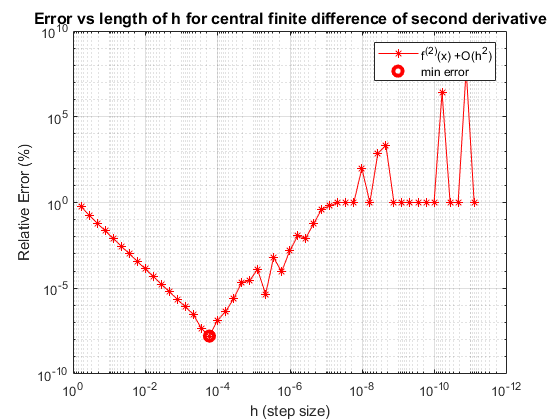

figure;
loglog(hs,error(2,:),'r-*')
hold on;
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
xlabel("h (step size)")
ylabel("Relative Error (%)")
grid
[t,s] = title("Error vs length of h for central finite difference of second derivative",' ');
t.FontSize = 12;
legend("f^{(2)}(x) +O(h^2)","min error")
tabErrors(2,1)= hs(idx);
tabErrors(2,2)= error(2,idx);
hold off

## Diferencia finita hacia adelante 

Similarmente a como despejamos la primera y segunda derivada de un sistema de ecuaciones de series de Taylor, podemos despejarlas de manera que sólo usemos puntos adelante de $x$, es decir, puntos de la forma $x+\left(n\right)h$ para $n\ge 0$.

### Primer derivada finita hacia adelante

$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x\right)}{h}+$$$ \mathcal{O}(h)$$                                             (a)

$f^{\prime } \left(x\right)\approx \frac{-\frac{1}{2}\;f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}+$$$ \mathcal{O}(h^2)$$             (b)

La ecuación (a) y (b) aproximan la primera derivada de $f\left(x\right)$, sin embargo (b) lo hace con mayor precisión, pues el error de truncamiento es de orden 2, y como $h\le 1\;$, el error se minimiza.

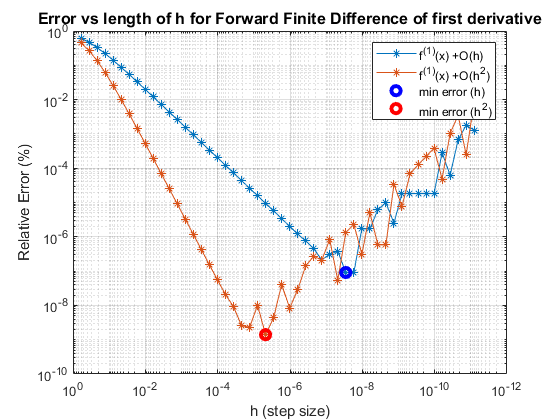


figure;
loglog(hs,error(3:4,:),"-*")
hold on
[minV,idx] = min(error(3,:));
loglog(hs(idx),error(3,idx),"b o",'MarkerSize',7,'LineWidth',3)
tabErrors(3,1)= hs(idx);
tabErrors(3,2)= error(3,idx);


[minV,idx] = min(error(4,:));
loglog(hs(idx),error(4,idx),"r o",'MarkerSize',7,'LineWidth',3)
tabErrors(4,1)= hs(idx);
tabErrors(4,2)= error(4,idx);
set(gca,'XDir','reverse')
grid
xlabel("h (step size)")
ylabel("Relative Error (%)")
[t,s] = title("Error vs length of h for Forward Finite Difference of first derivative",' ');
t.FontSize = 12;
legend("f^{(1)}(x) +O(h)","f^{(1)}(x) +O(h^2)","min error (h)","min error (h^2)")
hold off

### Segunda derivada finita hacia adelante

${f^{\prime } }^{\prime } \left(x\right)\approx \;\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }+$$$ \mathcal{O}(h)$$                                                  (a)

${f^{\prime } }^{\prime } \left(x\right)\approx \;\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }+$$$ \mathcal{O}(h^2)$$                        (b)

Al igual que con la primera derivada finita hacia adelante, la ecuación (b) aproxima a la segunda con mayor presición que la ecuación (a).

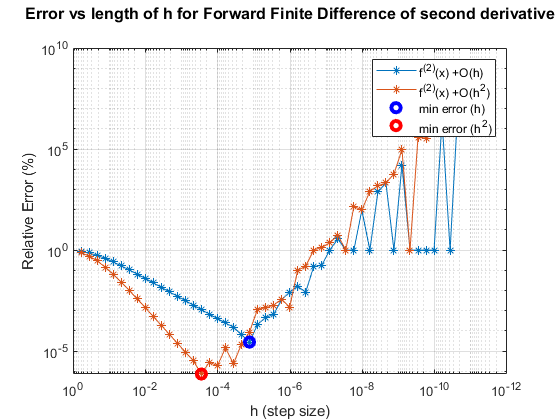

figure;
loglog(hs,error(5:6,:),"-*")
hold on
[minV,idx] = min(error(5,:));
loglog(hs(idx),error(5,idx),"b o",'MarkerSize',7,'LineWidth',3)
tabErrors(5,1)= hs(idx);
tabErrors(5,2)= error(5,idx);

[minV,idx] = min(error(6,:));
loglog(hs(idx),error(6,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
xlabel("h (step size)")
ylabel("Relative Error (%)")
[t,s] = title("Error vs length of h for Forward Finite Difference of second derivative", ' ');
t.FontSize = 12;
legend("f^{(2)}(x) +O(h)","f^{(2)}(x) +O(h^2)","min error (h)","min error (h^2)")
grid
tabErrors(6,1)= hs(idx);
tabErrors(6,2)= error(6,idx);
hold off

## Diferencia finita hacia atrás

Para la diferencia finita hacia atrás usamos la función valuada en $x$ y $x-h$, es decir, en lugar de los valores de $x$ y $x+h$ tenemos: $f\left(x\right)-f\left(x-h\right)$.

### Primera derivada finita hacia atrás

A continuación hay dos fórmulas para la primera derivada hacia atrás. La segunda (b) es más precisa pues para su elaboración se incorporan más términos de la serie de Taylor. 

$f^{\prime } \left(x\right)=\;\frac{f\left(x\right)-f\left(x-h\right)}{h}+$$$ \mathcal{O}(h)$$                                              (a)

$f^{\prime } \left(x\right)=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}+$$$ \mathcal{O}(h^2)$$                      (b)

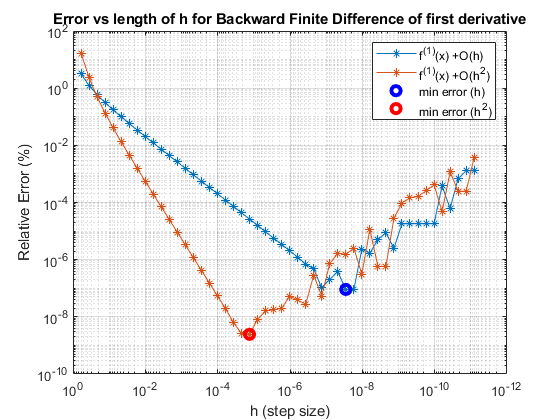

figure;
loglog(hs,error(7:8,:),"-*")
hold on
[minV,idx] = min(error(7,:));
loglog(hs(idx),error(7,idx),"b o",'MarkerSize',7,'LineWidth',3)
tabErrors(7,1)= hs(idx);
tabErrors(7,2)= error(7,idx);

[minV,idx] = min(error(8,:));
loglog(hs(idx),error(8,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
xlabel("h (step size)")
ylabel("Relative Error (%)")
title("Error vs length of h for Backward Finite Difference of first derivative",' ')
legend("f^{(1)}(x) +O(h)","f^{(1)}(x) +O(h^2)","min error (h)","min error (h^2)")
tabErrors(8,1)= hs(idx);
tabErrors(8,2)= error(8,idx);
hold off

#### Segunda derivada finita hacia atrás 

De la misma manera que para la primer derivada finita hacia atrás, la segunda fórmula (b) es más precisa que la primera (a).

${f^{\prime } }^{\prime } \left(x\right)=\frac{f\left(x\right)-2f\left(x-h\right)+f\left(x-2h\right)}{h^2 }+$$$ \mathcal{O}(h)$$                                         (a)

${f^{\prime } }^{\prime } \left(x\right)=\frac{2f\left(x\right)-5f\left(x-h\right)+4f\left(x-2h\right)-f\left(x-3h\right)}{\;h^2 }+$$$ \mathcal{O}(h^2)$$                (b)

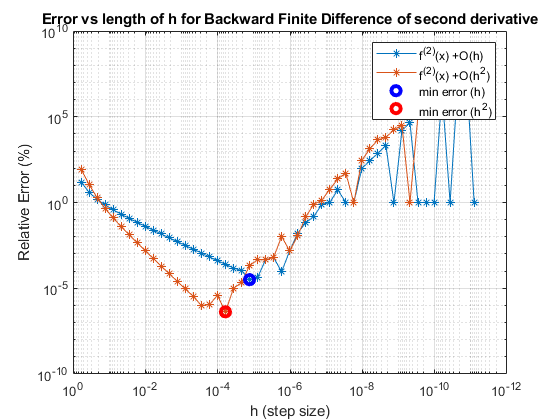


figure;
loglog(hs,error(9:10,:),"-*")
hold on
[minV,idx] = min(error(9,:));
loglog(hs(idx),error(9,idx),"b o",'MarkerSize',7,'LineWidth',3)
tabErrors(9,1)= hs(idx);
tabErrors(9,2)= error(9,idx);

[minV,idx] = min(error(10,:));
loglog(hs(idx),error(10,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
xlabel("h (step size)")
ylabel("Relative Error (%)")
title("Error vs length of h for Backward Finite Difference of second derivative",' ')
legend("f^{(2)}(x) +O(h)","f^{(2)}(x) +O(h^2)","min error (h)","min error (h^2)")
hold off

tabErrors(10,1)= hs(idx);
tabErrors(10,2)= error(10,idx);


## Conclusiones

El método númerico de Diferencia finita puede darnos muy buenas aproximaciones de las derivadas de una función, sin embargo hay que tener en cuenta las dos fuentes de error que mencionamos al principio.

#### Truncamiento

El error de truncamiento es natural para cualquier método derivado de una Serie de Taylor no convergente o truncada en sí misma (como es el caso de la diferencia finita). Lo único que podemos hacer para reducir este error de truncamiento es eligir una *h* muy pequeña. Irónicamente escoger un paso muy pequeño alrededor de la *x *cuya derivada queremos calcular nos lleva a la segunda fuente de error.

#### Redondeo

La precisión de los números en una computadora es siempre finita, y a diferencia de lenguajes como LISP, la memoria para un número en matlab está limitada. 

La doble precisión que ofrecen los números en matlab nos permiten usar una h bastante pequeña antes de incurrir en errores de redondeo. Sin embargo, mientras más términos tengamos que usen h y más operaciones realicemos con esto, mayor será el error de redondeo.

### Resultados

Podemos concluir que la mejor *h* para obtener la mejor precisión, es aquella que es lo más chica posible sin incurrir en errores de redondeo. Dicha *h* se puede aproximar de manera teórica sumando el residuo de lagrange junto con errores de redondeo equivalente al número de *h* usados en la función para aproximar[2]. Sin embargo necesitamos derivadas más profundas de la que estamos aproximando para obtener dicha h teórica por lo que no es práctico calcular está h de manera teórica. 

El resultado crucial de este estudio da respuesta de la siguiente pregunta: ***Si aumentar la precisión de la diferencia finita ocasiona que el error de truncamiento aparezca antes (a medida que hacemos h más chica) ¿Por qué el error es menor a medida que aumentamos los coeficientes que usan h? ***Es decir, cuando aumentamos la precisión de las formulas de diferencia finita.

cNames= {'1er Der. Central Ord 2','2da Der. Central Ord 2',...
    '1er Der. hacia adelante Ord 1', '1er Der. hacia adelante Ord 2'...
    '2da Der. hacia adelante Ord 1', '2da Der. hacia adelante Ord 2'...
    '1er Der. hacia atrás Ord 1', '1er Der. hacia atrás Ord 2'...
    '2da Der. hacia atrás Ord 1', '2da Der. hacia atrás Ord 2'  };
format shortE 
disp("Min. Error for every finite difference formula used above")

Min. Error for every finite difference formula used above


tab1= array2table(tabErrors,"RowNames", cNames, "VariableNames",{'Min. error h', 'Min. Relative Error'})

tab1 = 10×2 table
                                     Minimal error h    Relative Error
                                     _______________    ______________

    1er Der. Central Ord 2             7.8973e-06         3.4613e-10  
    2da Der. Central Ord 2             1.6927e-04         1.6271e-08  
    1er Der. hacia adelante Ord 1      2.8651e-08         9.0937e-08  
    1er Der. hacia adelante Ord 2      4.7384e-06         1.4012e-09  
    2da Der. hacia adelante Ord 1      1.3162e-05         2.8047e-05  
    2da Der. hacia adelante Ord 2      2.8211e-04         7.3556e-07  
    1er Der. hacia atrás Ord 1         2.8651e-08         9.0937e-08  
    1er Der. hacia atrás Ord 2         1.3162e-05         2.4429e-09  
    2da Der. hacia atrás Ord 1         1.3162e-05 

Como se puede observar en las gráficas de las diferencias finitas hacia delante y hacia atrás, ademas de la tabla con los valores de *h *que minimizan el error total, las funciones con orden de precisión 2, es decir con $h^2$ incurren en menor error. La causa de este resultado se debe a que el error de truncamiento escala de forma cuadratica (de forma inversa porque $h<1$). Por otra parte, las operaciones que ocasionan el error de redondeo son lineales. A esto hay que agregar que la precisión que ofrencen los numeros double de matlab IEEE 754 es lo suficiente como para poder reduciar h bastante antes de incurrir en errores de redondeo. 

### M-ésima derivada con precisión n.

A pesar de lo dicho anteriormente acerca de $O\left(h\right)\;\textrm{vs}\;O\left(h^2 \right)$. Esto no se sostiene a medida que aumentamos la precisión. Es cierto que cada vez incurriremos antes en errores de redondeo, por lo que necesitariamos evaluar menos valores de h y no reducirla tanto para alcanzar la mejor aproximación. Sin embargo debido a la precisión limitada de los IEEE 754 con doble precisión (y a los numeros dentro de una computadora en general), al aumentar la el grado de precisión,  eventualmente alcanzaremos el error de redondeo tan rápido que no abrá forma de reducir *h *para reducir el error de truncamiento de las series de Taylor.

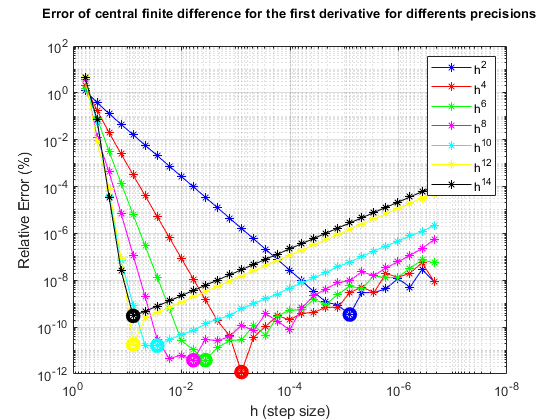

pre=2:2:14; % 2,4,6,8 y 10
m=1;      %primera derivada
hs = arr(1:30);
error           = zeros([5,length(hs)]);
approximations  = zeros([1,5]);

for n = pre
    n_coefs=2*floor((m+1)/2)-1+n; p=(n_coefs-1)/2;  %calculations for coefficients matrix taken from [3]  
    A=power(-p:p,(0:2*p)'); 
    b=zeros(2*p+1,1); 
    b(m+1)=factorial(m); 
    c=A\b; 
    
    j=1;
    for h = hs
        k=-p;
        ffd = 0;
        for cof =c'           
            ffd = ffd+ cof*func1(x+k*h);            
            k=k+1;
        end
        ffd=ffd/(h^m);
        error(n/2,j)= abs(ffd/df_x -1);
        j=j+1;
    end
    
end
figure
l(1) = loglog(hs,error(1,:),"b-*");
hold on
l(2) = loglog(hs,error(2,:),"r-*");
l(3) = loglog(hs,error(3,:),"g-*");
l(4) = loglog(hs,error(4,:),"m-*");
l(5) = loglog(hs,error(5,:),"c-*");
l(6) = loglog(hs,error(6,:),"y-*");
l(7) = loglog(hs,error(7,:),"k-*");
set(gca,'XDir','reverse');
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"b o",'MarkerSize',8,'LineWidth',3)
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',8,'LineWidth',3)
[minV,idx] = min(error(3,:));
loglog(hs(idx),error(3,idx),"g o",'MarkerSize',8,'LineWidth',3)
[minV,idx] = min(error(4,:));
loglog(hs(idx),error(4,idx),"m o",'MarkerSize',8,'LineWidth',3)
[minV,idx] = min(error(5,:));
loglog(hs(idx),error(5,idx),"c o",'MarkerSize',8,'LineWidth',3)
[minV,idx] = min(error(6,:));
loglog(hs(idx),error(6,idx),"y o",'MarkerSize',8,'LineWidth',3)
[minV,idx] = min(error(7,:));
loglog(hs(idx),error(7,idx),"k o",'MarkerSize',8,'LineWidth',3)
xlabel("h (step size)")
ylabel("Relative Error (%)")
title("\fontsize{10}Error of central finite difference for the first derivative for differents precisions",' ')
legend(l(1: 7),'h^2','h^4','h^6','h^8','h^{10}','h^{12}','h^{14}');
grid
hold off

En esta gráfica podemos observar que un mayor orden de precisión no se traduce en un menor error necesariamente. Va a incurrir en un menor error para valores de *h* antes de que ésta decrezca demasiado, sin embargo, a mayor precisión incurrira antes en errores de redonde por el espacio limitado para almacenar un número en la máquina. En el caso de las preciones altas, como es el caso de $O\left(h^{14} \right)$, se incurrirá en un error de redondeo tan rápido (debido a todas las operaciones que se hacen con *h *para aproximar la diferencial), que no tendremos espacio para reducir el error de truncamiento al reducir el valor de h. 

## Bibliografía

    [1] J. Kiusalaas, "Numerical Differentiation," in *Numerical Methods in Engineering with MATLAB*, first edition. New York,           NY, USA: Cambridge University Press, 2005, pp: 182-187.

    [2] S.C.Chapra, "Roundoff and Truncation Errors," in *Applied Numerical Methods with MATLAB for Engineers and Scientists *, 4th edition, New York, NY, USA: McGraw-Hill Education, 2018, pp: 125-130

    [3] M. Baer, *findiff*, github.com. [https://github.com/maroba/findiff](https://github.com/maroba/findiff) (accessed Jun. 22, 2021)

## Apéndice

Las funciones utilizadas se encuentran a continuación

function ffd = backwardFiniteDifference(f,x,h,m,n)
%reject if m>2 or n>2
coefficients = [NaN NaN 1 -1 ;
                NaN 3/2 -2 1/2];
coefficients(:,:,2) = [ NaN 1 -2 1 ;
                        2 -5 4 -1];

c = coefficients(n,:,m);
c = c(not(isnan(c)));

ffd = 0;
i=0;
    for cof =c
        ffd = ffd+ cof*f(x-i*h);
        i=i+1;
    end
    ffd=ffd/(h^m);
end

function ffd = forwardFiniteDifference(f,x,h,m,n)
%reject if m>2 or n>2
coefficients = [-1 1 NaN NaN;
                -3/2 2 -1/2 NaN];
coefficients(:,:,2) = [1 -2 1 NaN;
                        2 -5 4 -1];

c = coefficients(n,:,m);
c = c(not(isnan(c)));

ffd = 0;
i=0;
    for cof =c
        ffd = ffd+ cof*f(x+i*h);
        i=i+1;
    end
    ffd=ffd/(h^m);
end

function fcd = firstCenteredDerivative(f,x,h)
%first centered derivative
fcd = (f(x+h)-f(x-h))/(2*h);
end

function scd = secondCenteredDerivative(f,x,h)
%first centered derivative
scd = (f(x+h)-2*f(x)+f(x-h))/(h^2);
end
